# Ejercicio - Redacción de requisitos

Este ejercicio introduce conceptos básicos sobre la redacción de requisitos. 

**El objetivo principal es redactar los requisitos de un motor de patinete a partir de los requisitos del cliente indicados en este documento.**

La empresa MU ScootersInc. busca un proveedor de motores eléctricos. Usted (estudiante) forma parte de una empresa que fabrica motores eléctricos.

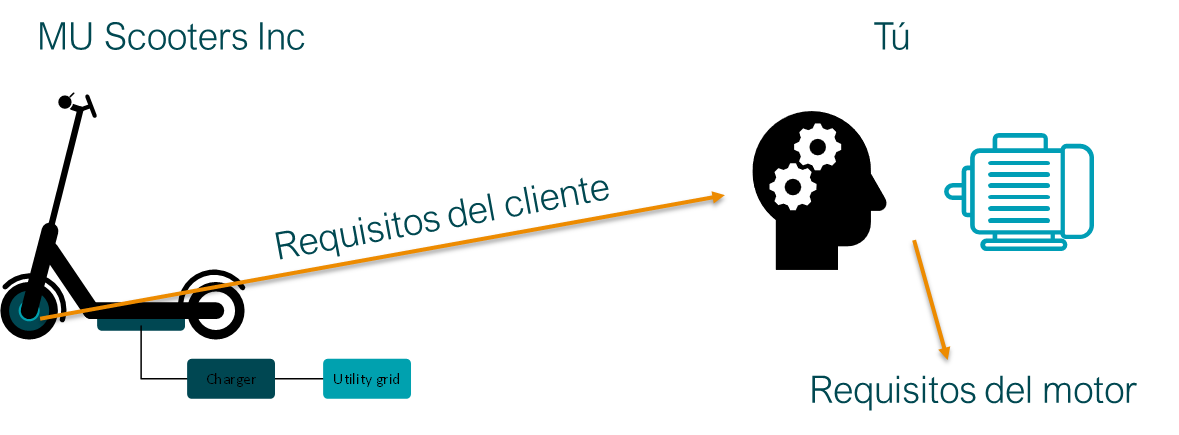

El ejercicio consistirá en las siguientes tareas:

- Lea atentamente los requisitos del cliente que figuran en las siguientes diapositivas. Recuerde que estos requisitos pueden darse de manera informal y no estructurada. El objetivo es convertir lo que pide el cliente en requisitos formales para el motor.

- Empiece a escribir dos requisitos para el motor. 

- Cree un conjunto de requisitos y requisitos en el Editor de requisitos de MATLAB.

- Complete los atributos presentes en el Editor de requisitos.

- Complete todo el conjunto de requisitos teniendo en cuenta la información facilitada por el cliente. Redacte al menos 10 requisitos funcionales y 5 no funcionales.

Tenga en cuenta las pautas dadas en la teoría de clase. El ejercicio se evaluará siguiendo dichas directrices.

El entregable contendrá un archivo de conjunto de requisitos MALTAB (slreqx) y un archivo wordimportado directamente del editor.

## 1. Introducción

### 1.1 Propósito

Este documento ha sido elaborado por MU Scooters Inc. Presenta los requisitos para un motor de scooter eléctrico. Su objetivo es ayudar a los proveedores a especificar los requisitos del motor.

### 1.2 Antecedentes y contexto

MU Scooters Inc. está diseñando y fabricando un scooter eléctrico para movilidad urbana. La arquitectura del scooter se muestra en la siguiente figura.

Será un scooter de dos ruedas con chasis ligero de aluminio y una velocidad máxima de 25 km/h. Se espera un peso máximo de 4 kg (incluidas todas las piezas).

La batería (24 V) y la electrónica irán debajo de la estructura. Se utilizará un motor en la rueda con una rueda hinchable de 10 pulgadas.

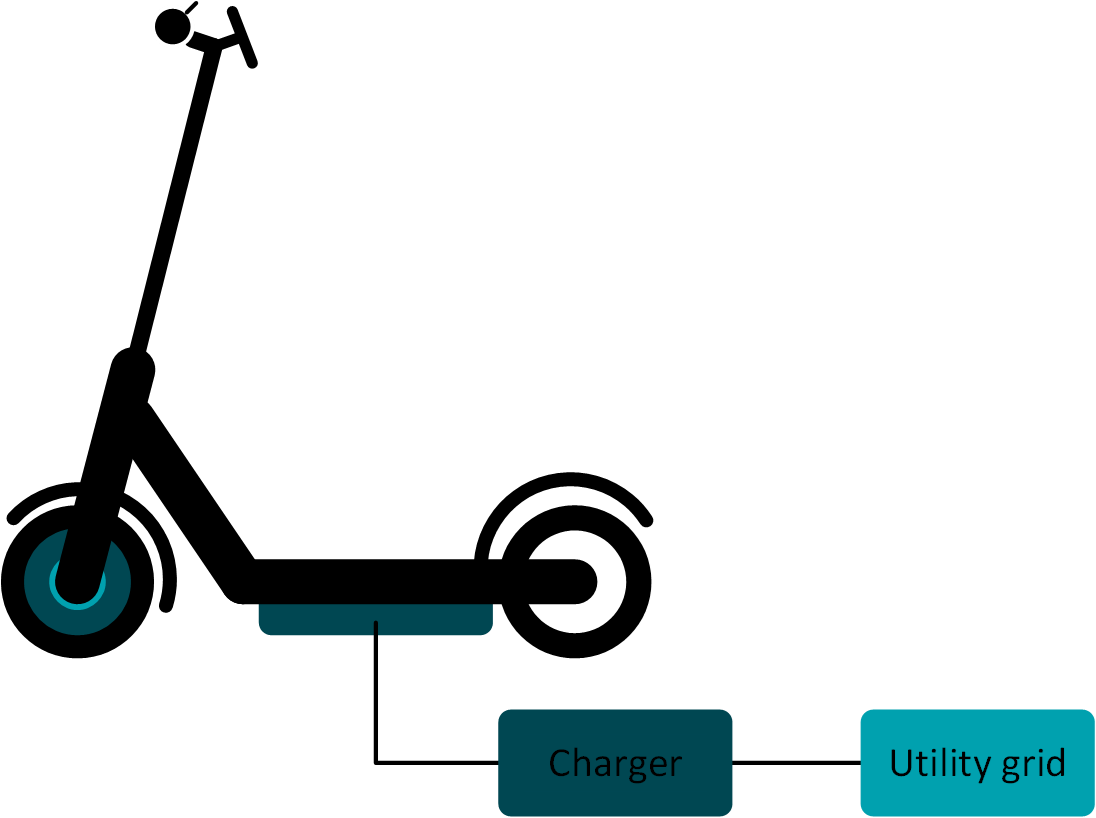

El scooter se venderá junto con un cargador de batería. En cuanto a la conectividad, el scooter tendrá una pantalla de 4,7" con conectividad bluetooth. La pantalla se utilizará para mostrar información sobre el estado de carga de la batería y el manejo de la información del GPS.

## 2. Características del motor

Para dimensionar el motor, Mu Scooters Inc. ha simulado varias rutas. El comportamiento dinámico de las rutas se almacenó en archivos .mat.

### Información dinámica de la ruta

Hay tres rutas de ejemplo

routeSelect = "Route 3";
switch routeSelect
    case "Route 1"
        load dynamicsGalarreta2Anoeta
    case "Route 2"
        load dynamicsGros2Ulia
    case "Route 3"
        load dynamicsGros2Ibaeta
    otherwise
        load dynamicsGalarreta2Anoeta
end

### Curvas de par y velocidad

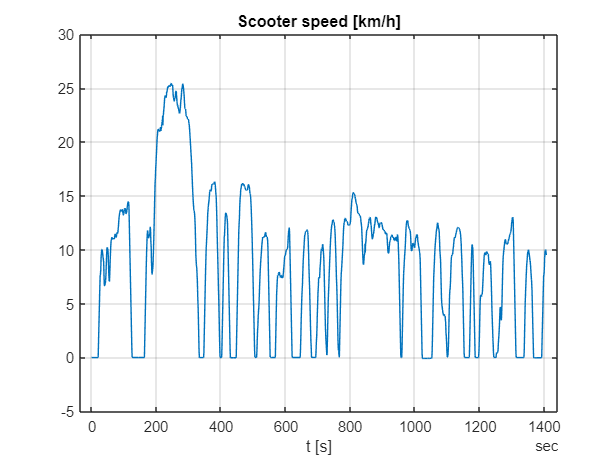

% Speed
plot(logsout{3}.Values.vScooter__km_h_.Time,logsout{3}.Values.vScooter__km_h_.Data)
title('Scooter speed [km/h]')
xlabel('t [s]')
grid

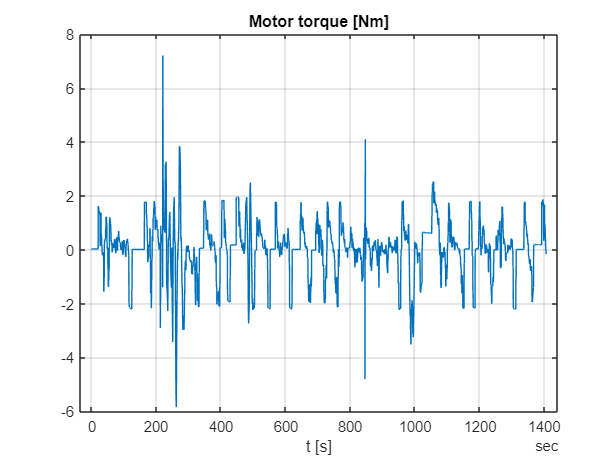


% Torque
plot(logsout{2}.Values.TemRef.Time,logsout{2}.Values.TemRef.Data)
title('Motor torque [Nm]')
xlabel('t [s]')
grid

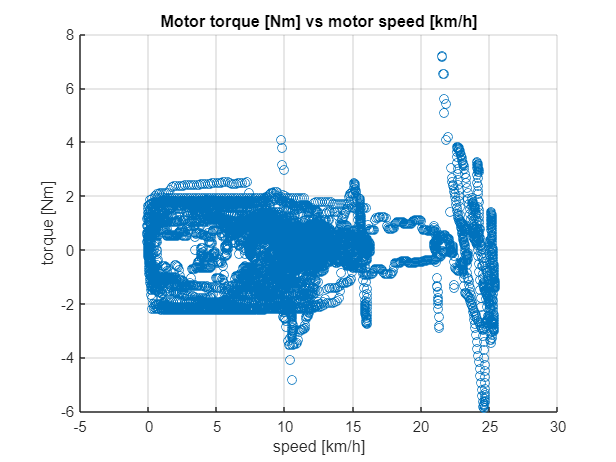

% Torque speed curve
%% Torque speed curve
scatter(logsout{3}.Values.vScooter__km_h_.Data,logsout{2}.Values.TemRef.Data)
title('Motor torque [Nm] vs motor speed [km/h]')
xlabel('speed [km/h]')
ylabel('torque [Nm]')
grid

### Par equivalente, máximo y mínimo de ruta

A continuación se calculan el par equivalente rms, el par máximo y el par mínimo por ruta.

Par rms equivalente:

Trms = rms(logsout{2}.Values.TemRef.Data)

Trms = 1.0335

Par máximo:

Tmax = max(logsout{2}.Values.TemRef.Data)

Tmax = 7.2036

Par mínimo:

Tmin = min(logsout{2}.Values.TemRef.Data)

Tmin = -5.8428

Velocidad máixma

vMax = max(logsout{3}.Values.vScooter__km_h_.Data)

vMax = 25.4384

*Copyright 2022 Mondragon Goi Eskola Politeknikoa.*

[*www.mondragon.edu/msie*](http://www.mondragon.edu/msie)

*jdelolmo@mondragon.edu*